# The SIM/subtract_proper method

# in the Astronomy & Astrophysics package for MATLAB

## Description:

The `SIM/subtract_proper` method is an image subtraction function based on the [Zackay, Ofek & Gal-Yam (2016)](http://adsabs.harvard.edu/abs/2016ApJ...830...27Z) algorithm (hereafter ZOGY). The function works with [SIM objects](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/SIM.html), and can perform most of the required pre-processing, including source extraction, flux matching and registration. The function can be used for transient detection and flux measurments in the difference image. 

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O) and  [Zackay, Ofek & Gal-Yam (2016)](http://adsabs.harvard.edu/abs/2016ApJ...830...27Z).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

## Introduction to ZOGY

Transient detection and flux measurement via image subtraction stand at the base of time domain astronomy. Due to the varying seeing conditions, the image subtraction process is non-trivial, and previous solutions suffer from a variety of problems. In [Zackay, Ofek & Gal-Yam (2016)](http://adsabs.harvard.edu/abs/2016ApJ...830...27Z), starting from basic statistical principles, we develop the optimal statistic for transient detection, flux measurement, and any image-difference hypothesis testing. We derive a closed-form statistic that: (1) is mathematically proven to be the optimal transient detection statistic in the limit of background-dominated noise, (2) is numerically stable, (3) for accurately registered, adequately sampled images, does not leave subtraction or deconvolution artifacts, (4) allows automatic transient detection to the theoretical sensitivity limit by providing credible detection significance, (5) has uncorrelated white noise, (6) is a sufficient statistic for any further statistical test on the difference image, and, in particular, allows us to distinguish particle hits and other image artifacts from real transients, (7) is symmetric to the exchange of the new and reference images, (8) is at least an order of magnitude faster to compute than some popular methods, and (9) is straightforward to implement. Furthermore, we present extensions of this method that make it resilient to registration errors, color-refraction errors, and any noise source that can be modeled. In addition, we show that the optimal way to prepare a reference image is the proper image coaddition presented in [Zackay & Ofek (2016)](http://adsabs.harvard.edu/abs/2015arXiv151206879Z). 

## Older version

An older version of the `SIM/subtract_proper` method is available in `AstroIm.imsub_fft`. However, this version is not supported.

## General notes and tips about image subtraction

# Examples

The` SIM/subtract_proper` can subtract two registered images. The first step is to read images into SIM objects:

S1 = FITS.read2sim('PTF_20141122*100037_c02.fits');

In this specific example, S1 now contain two images. Next we would like to extract sources, estimate the PSF.

S1 = gain_correct(S1);
S1 = mextractor(S1);

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std
 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 1254819.656688 



 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 1210799.391164 



  Subtract background
mextractor image 1 out of 2
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2884 sources
  Calculate 1st and 2nd moments
mextractor image 2 out of 2
  Filter image number 2 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2869 sources
  Calculate 1st and 2nd moments
mextractor second pass - Source detection and measurments
  Subtract background
mextractor image 1 out of 2
  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 6723 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)
41 CR flagged in image 1
mextractor image 2 out of 2
  Filter image number 2 - use 2 filters
    Threshold image and locate local maxima
    Extracting 6554 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)
37 CR flagged in 

S1 now contains, for each image, its background image, noise image, source catalog and PSF. For example, you can plot the PSF of the first image:

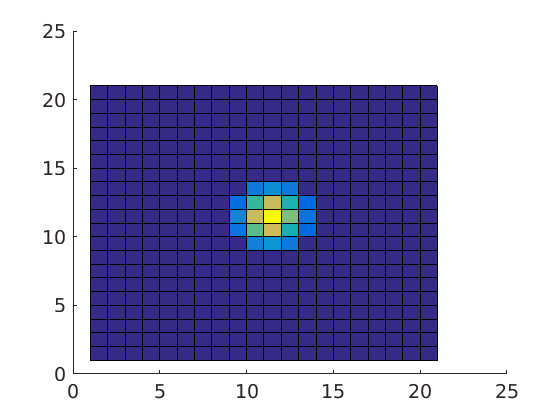

surface(S1(1).PSF)

Next we can regsiter the images

[AS1,FitTran] = align(S1,S1(2));

Iep =      1


Iep =      2


Iep =      3


SIM/transform: WCS was not corrected
SIM/transform: WCS was not corrected


Note that by default the `SIM/align` method uses the 'AlignMethod' equal 'wcsCoo'. In some cases you may like to use a different option (see `help SIM/align` for more options).

To verify that the images are registered you can display them using ds9 and blink them

ds9(AS1);  % read the two images into ds9

FitTran
eran     40090  1.0  0.0 147340 45936 pts/38   S    15:26   0:05 ds9
ds9 is already open


Note that by default (unless specified otherwise), `SIM/align` will set the value of non-overlapping pixels to NaN, and in this case the image subtraction will fail. In order to mitigate this you can replace this NaN values by the mean background level (e.g., using `SIM/replace_with_noise`), or trim the images.

AS1=trim_image(AS1,[11 1000 11 1000]);

Next, we can estimate the relative zero point (or flux matching) between the two images:

 [ZP,Fzp,ResZP]=zp_estimate(AS1,2,'SkipWCS',true,...
                         'Columns',{'XWIN_IMAGE','YWIN_IMAGE','MAG_PSF','MAGERR_PSF'},...
                                              'MagCol','MAG_PSF',...
                                              'MagErrCol','MAGERR_PSF');
        

 Finally, we can subtract the two images:

[Summary,D,S,Scorr,SigmaF]=subtract_proper(AS1(1),AS1(2),...
    'FluxMatch',Fzp(1),'SigmaX',FitTran(1).rrms,'SigmaY',FitTran(1).rrms);

  Set gain to 1
  Subtract background
  Set gain to 1
  Subtract background


Note that `SIM/subtract_proper` has many options including the ability to perform many of the pre-processing steps. However, for clarity we gave a step by step example. In this example, the 'FluxMatch' keyword value contains the flux matching between the two images, and the 'SigmaX' and 'SigmaY' contain the registration error in pixels.

**The output:**

`Summary:` A structure array containing the following fields:

- `Beta`: The flux matching parameter

- `FD`: The flux normalization for the D image (Equation 15 in ZOGY).

- `F_S`: The flux normalization for the S image (Equation 42 in ZOGY). The flux of the transients in units of the zero point of the reference image is given by dividing S at the position of the transient local maxima by F_S (i.e., Equation 41 in ZOGY).

- `SigmaFlux`: Flux error matrix for each pixel in the image (Equation 43 in ZOGY). This does not include source noise or astrometric noise.

`D`: A SIM object containing the proper subtraction image (Equation 13 in ZOGY). The PSF (Equation 14 in ZOGY) is stored in `D.PSF`. This is useful in order to look for cosmic rays in images.

`S`: The transient detection statistics not corrected for source noise and astrometric noise (Equation 12 in ZOGY). This is useful in order to measure flux of transients.

`Scorr`: The transient detection statistics corrected for source noise and astrometric noise (Equation 25 in ZOGY). This is useful in order to search for transients.

`SigmaF`: like `SigmaFlux`.